% Řešení okrajového problému - vykreslení w(x) a dw/dx
clear all; close all; clc;

% Parametry
l = 1;           % délka (můžeš změnit)
lambda = 3.5;    % parametr lambda (můžeš změnit)

% Výpočet konstant
% Jmenovatel D
D = 2*(1 - cos(lambda)) - lambda*sin(lambda);

% Konstanty
c4 = (1 - cos(lambda)) / D;
c3 = c4 * sin(lambda) / (cos(lambda) - 1);
c2 = -lambda/l * c3;
c1 = 1 - c4;

% Zobrazení konstant
fprintf('Parametry:\n');

Parametry:


fprintf('l = %.4f\n', l);

l = 1.0000


fprintf('lambda = %.4f\n\n', lambda);

lambda = 3.5000



fprintf('Konstanty:\n');

Konstanty:


fprintf('c1 = %.6f\n', c1);

c1 = 0.620351


fprintf('c2 = %.6f\n', c2);

c2 = -0.240703


fprintf('c3 = %.6f\n', c3);

c3 = 0.068772


fprintf('c4 = %.6f\n\n', c4);

c4 = 0.379649




% Definice x
x = linspace(0, l, 1000);

% Funkce w(x)
w = c1 + c2*x + c3*sin(lambda/l*x) + c4*cos(lambda/l*x);

% Derivace dw/dx
dw = c2 + c3*(lambda/l)*cos(lambda/l*x) - c4*(lambda/l)*sin(lambda/l*x);

% Ověření okrajových podmínek
fprintf('Ověření okrajových podmínek:\n');

Ověření okrajových podmínek:


fprintf('w(0) = %.6f  (má být 1)\n', w(1));

w(0) = 1.000000  (má být 1)


fprintf('w(l) = %.6f  (má být 0)\n', w(end));

w(l) = 0.000000  (má být 0)


fprintf('dw(0)/dx = %.6f  (má být 0)\n', dw(1));

dw(0)/dx = 0.000000  (má být 0)


fprintf('dw(l)/dx = %.6f  (má být 0)\n\n', dw(end));

dw(l)/dx = 0.000000  (má být 0)



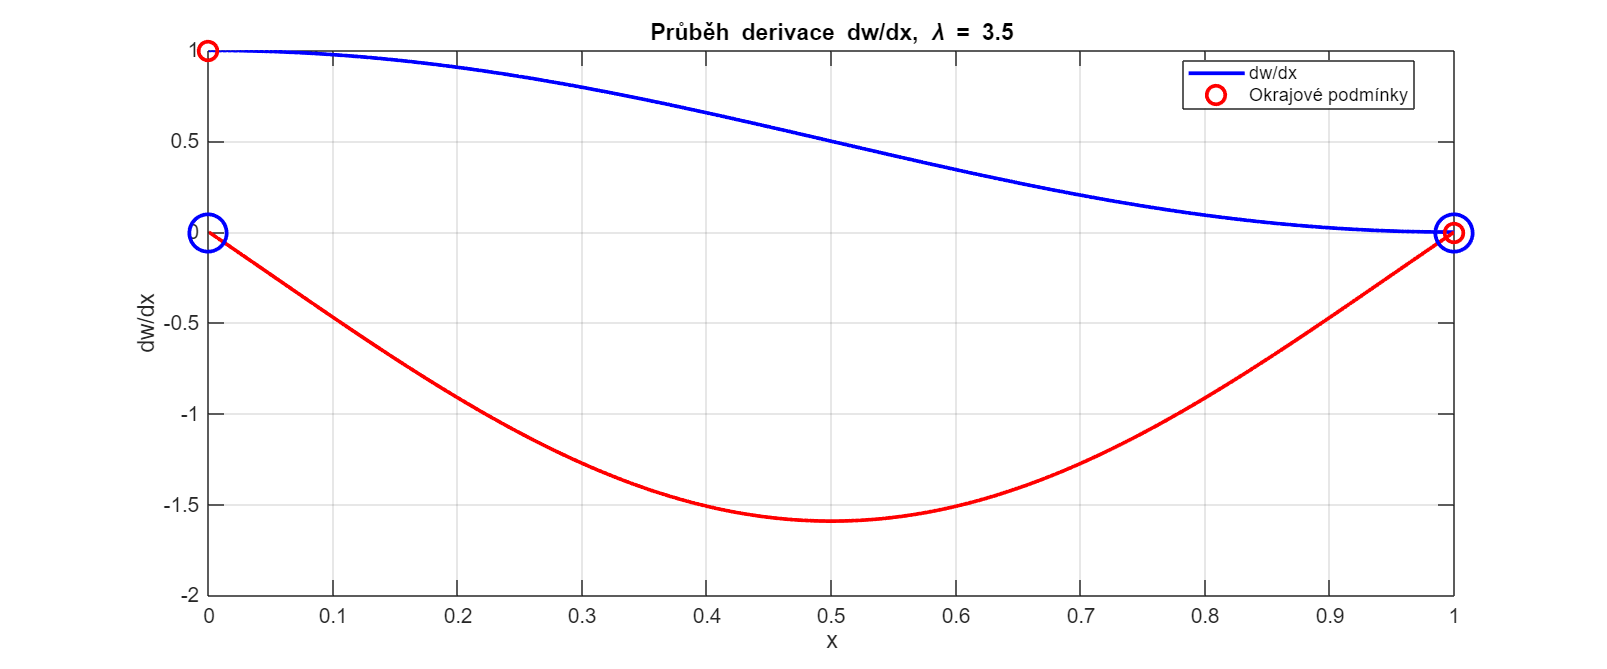


% Vykreslení
figure('Position', [100, 100, 1200, 500]);

% Graf w(x)
plot(x, w, 'b-', 'LineWidth', 2);
grid on;
xlabel('x', 'FontSize', 12);
ylabel('w(x)', 'FontSize', 12);
title(['Průběh funkce w(x), \lambda = ', num2str(lambda)], 'FontSize', 14);
% Označení okrajových bodů
hold on;
plot(0, w(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot(l, w(end), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
legend('w(x)', 'Okrajové podmínky', 'Location', 'best');
set(gca, 'FontSize', 11);

% Graf dw/dx
plot(x, dw, 'r-', 'LineWidth', 2);
grid on;
xlabel('x', 'FontSize', 12);
ylabel('dw/dx', 'FontSize', 12);
title(['Průběh derivace dw/dx, \lambda = ', num2str(lambda)], 'FontSize', 14);
% Označení okrajových bodů
hold on;
plot(0, dw(1), 'bo', 'MarkerSize', 20, 'LineWidth', 2)
plot(l, dw(end), 'bo', 'MarkerSize', 20, 'LineWidth', 2)
legend('dw/dx', 'Okrajové podmínky', 'Location', 'best');
set(gca, 'FontSize', 11);